% Bar plot
% Data: Global Co2 emission (2010 - 2020)
year = 2010:1:2020

year =         2010        2011        2012        2013        2014        2015        2016        2017        2018        2019        2020


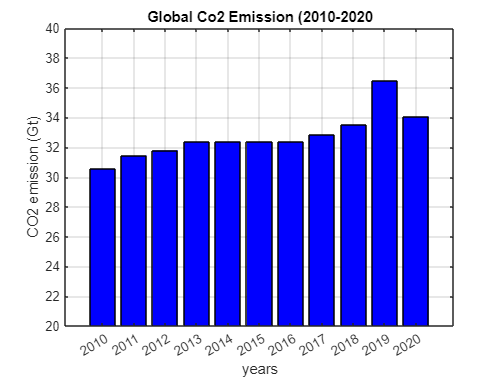

Co2 = [30.5824 31.4595 31.806 32.3707 32.3886 32.3655 ...
        32.3747 32.8374 33.5133 36.4568 34.0752];
bar(year,Co2,'blue');
ylim([20 40]);
xlabel('years')
ylabel('CO2 emission (Gt)')
title('Global Co2 Emission (2010-2020')
grid on

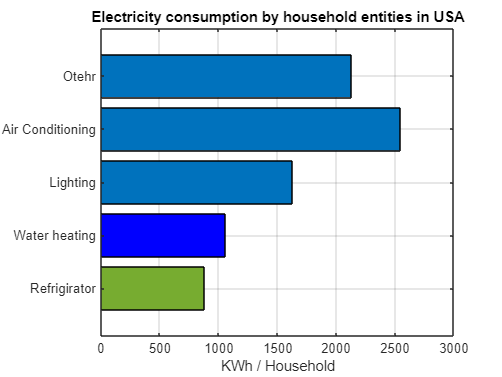

% Horizontal bar plot
% Data: Electricity consumption by household entities in USA
X = categorical({'Refrigirator', 'Water heating', 'Lighting', 'Air Conditioning', 'Otehr'});
X = reordercats(X,{'Refrigirator', 'Water heating', 'Lighting', 'Air Conditioning', 'Otehr'});
Y = [879 1056 1628 2545 2127];
C = barh(X,Y);
C.FaceColor = 'flat';
C.CData(1,:) = [0 1 1];
C.CData(2,:) = [0 0 1];
C.CData(3,:) = [0 0.4470 0.7410];
C.CData(1,:) = [0 1 0];
C.CData(1,:) = [0.4660 0.6740 0.1880];
xlabel('KWh / Household');
title('Electricity consumption by household entities in USA')
grid on

% Area plot 
% Data: Typical load curve over 24 hours in 
clc;
a = xlsread('Area_plot_2.xlsx');

Error using xlsread (line 27)
Unable to open file 'Area_plot_2.xlsx'.
File 'C:\Users\goodn\Desktop\Matlab_Learn\Area_plot_2.xlsx' not found.

y = a(:,2:4)
area(y);
xlim([0 24]);
xlabel('Hours');
ylabel('Load (MW)');
title('Load curve in MW')
legend('Base load', 'Shoulder load', 'Peak load', 'Location','northwest');
